close all
clear

a = 2

a = 2

b = 3

b = 3


x = linspace(a,b,1e5);
xx = linspace(a,b,1e5);

f1 = @(z) (sqrt(z.^2-1)-z);
f2 = @(z) -(1./sqrt(z.^2-1));
f3 = @(z) -(sqrt((z+1)./(z-1))-1);

mmax = 50

mmax = 50

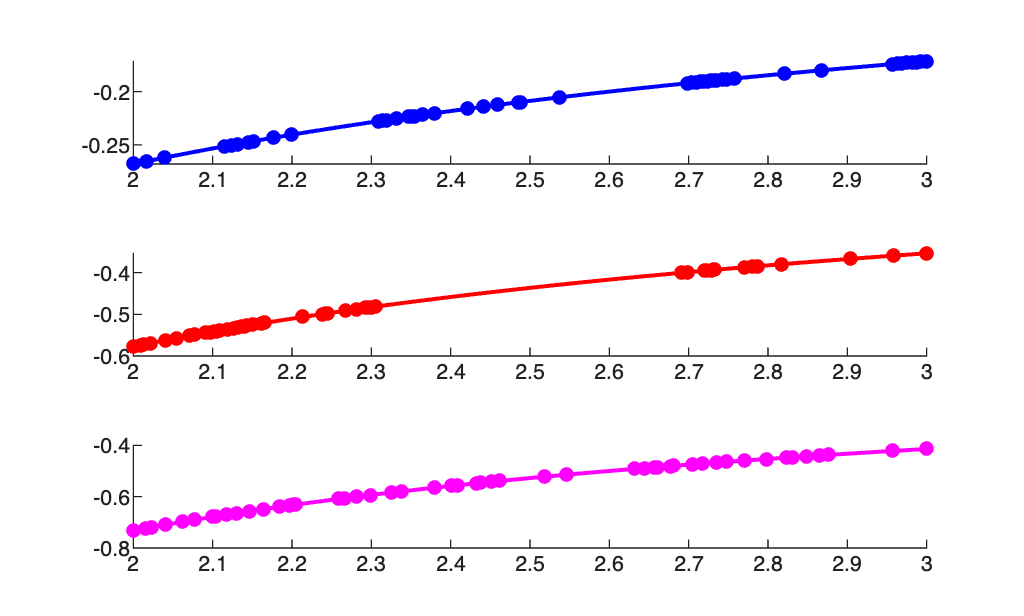

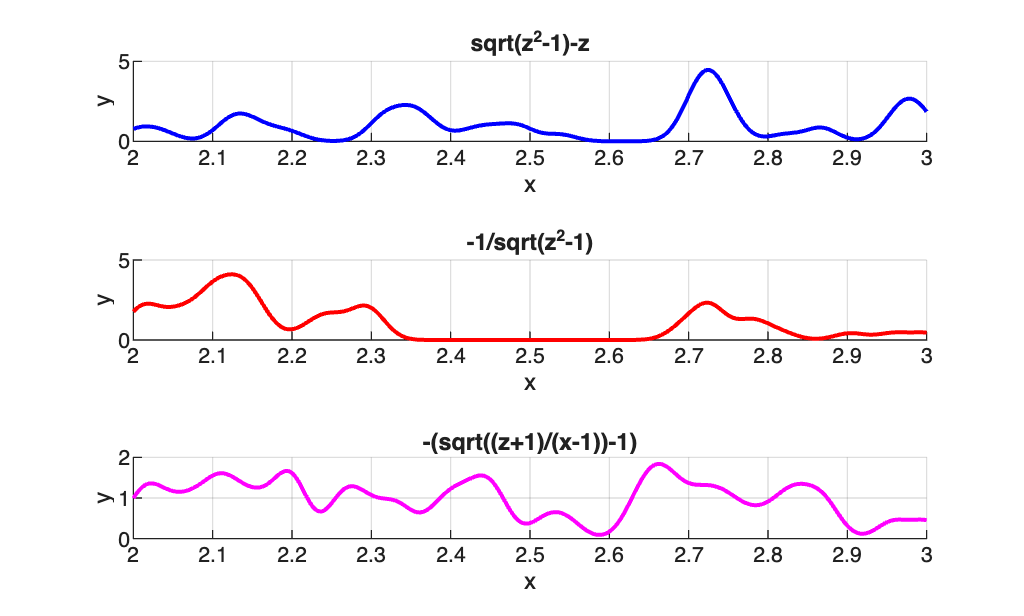

h = 0.02;   % KDE bandwidth


funcs = {f1,f2,f3};
names = {"sqrt(z^2-1)-z","-1/sqrt(z^2-1)","-(sqrt((z+1)/(x-1))-1)"};
colors = {"b","r","m"};

fig1 = figure;
layout1 = tiledlayout(fig1,3,1);

fig2 = figure;
layout2 = tiledlayout(fig2,3,1);

for k = 1:3

    f = funcs{k};
    y = f(x);

    [r,pol,res,zer,zj] = aaa(y,x,"mmax",mmax,"tol",0);

    nexttile(layout1)
    hold on

    plot(xx,f(xx),"k","LineWidth",1.2)
    plot(xx,r(xx),"Color",colors{k},"LineWidth",1.5)
    plot(zj,f(zj),"o","Color",colors{k},"MarkerFaceColor",colors{k},"MarkerSize",5)


    %

    nexttile(layout2)
    hold on

    kde_vals = myKDE(xx, zj, h, a, b);

    plot(xx, kde_vals, "Color", colors{k}, "LineWidth", 1.5)
    grid on
    xlabel("x")
    ylabel("density")
    title("KDE of support points: " + names{k})
    %

    grid on
    xlabel("x")
    ylabel("y")
    title(names{k})
end